5.4 그래프 형식 지정

그래프에 제목 달고, x축, y축 제목 표시하고, 격자(grid) 표시하기, 축 범위 재설정 하기 등 의 작업.

**text(****x,y****, ‘****텍스트’****): (****x,y****) ****위치에 ‘텍스트’의 첫 글자가 위치하도록 표시한다****. **

**title(‘****텍스트’****): 그래프 윗부분에 ‘텍스트’****를**** 제목으로 표시한다****.**

**xlabel****(‘****텍스트****’****): 그래프의 가로축에 ‘텍스트’****를**** 축 라벨로 표시한다****.**

**ylabel****(‘****텍스트****’****): 그래프의 세로축에 ‘텍스트’****를**** 라벨로 표시한다****.**

**axis: axis( ****[****xmin**  **xmax**  **ymin**  **ymax****]**** ) : ****좌표축 범위 지정**

**grid [on/****off****] : 그래프 바탕에 격자****(grid)****를 표시하거나 지운다****.**

**legend(****‘s1’, ‘s2’,** **…,**  **pos): 선 종류와 입력한 문자열을 지정한 위치****(pos)****에 표시한다.**

x=[-2:0.01:4];
y=3*x.^3-26*x+6;
yd=9*x.^2 - 26;
ydd = 18*x;
plot(x, y, '-b')
hold on
plot( x, yd,'--r')
plot( x, ydd,':k')
hold off
legend('원함수','1차미분','2차미분');
title('어느함수와 그 미분 함수들');
xlabel('x');
ylabel('함수값');
text(1.5,100,'legend')

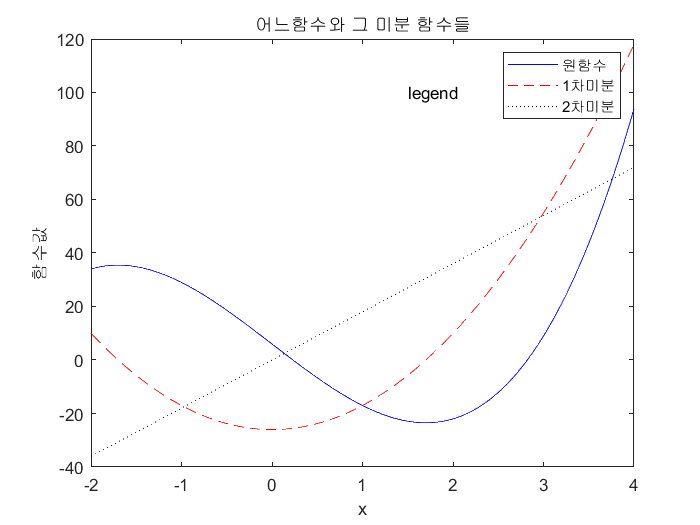

x=[-2:0.01:4];
y=3*x.^3-26*x+6;
yd=9*x.^2 - 26;
ydd = 18*x;
plot(x, y, '-b')
hold on
plot( x, yd,'--r')
plot( x, ydd,':k')
hold off
legend('원함수','1차미분','2차미분');

title('어느함수와 그 미분 함수들');
xlabel('x');
ylabel('함수값');
text(1.5,100,'legend','FontSize',14)

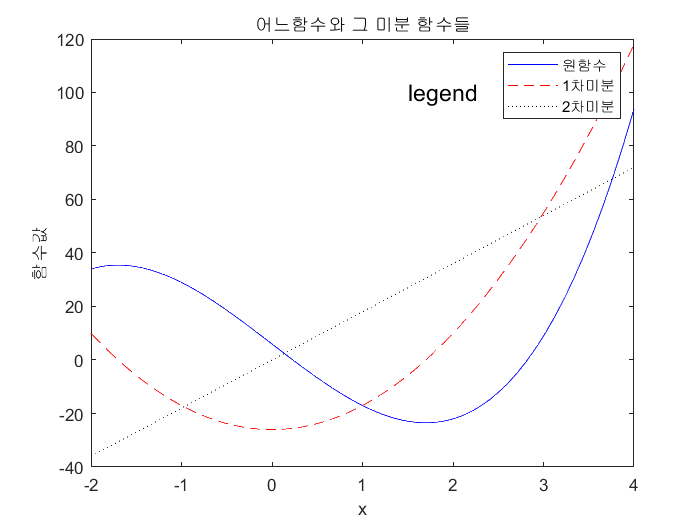

x=[-2:0.01:4];
y=3*x.^3-26*x+6;
yd=9*x.^2 - 26;
ydd = 18*x;
plot(x, y, '-b')
hold on
plot( x, yd,'--r')
plot( x, ydd,':k')
hold off
legend('원함수','1차미분','2차미분');
title('어느함수와 그 미분 함수들','FontSize',14);

xlabel('x','FontSize',14);
ylabel('함수값','FontSize',14);
text(1.5,100,'legend','FontSize',14)

axis 명령어는 좌표축의 범위와 모양을 변경할 때 사용된다.  

**axis: axis( [xmin  xmax  ymin  ymax] ) : 좌표축 범위 지정**

% 그래프 그리기
x = 0: 0.02: pi/2;
plot(x, tan(x), '-ro')
%axis([0  pi/2  0  100])

% 최대값에 맞추어 설정된 좌표축의 재설정
% 그래프 그리기
x = 0: 0.02: pi/2;
plot(x, tan(x), '-ro')
axis([0  pi/2  0  5])

grid 명령어

grid on     그래프에 격자선(grid)을 추가함

grid off    그래프에서 격자선(grid)을 제거함

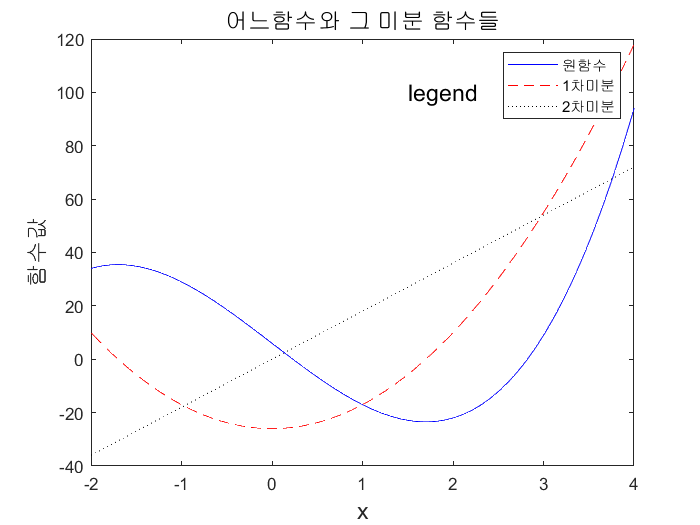

% 최대값에 맞추어 설정된 좌표축의 재설정
% 그래프 그리기
x = 0: 0.02: pi/2;

plot(x, tan(x), '-ro')
axis([0  pi/2  0  5])
grid on

5.5 로그 축 그래프

semilogy(x, y): x축이 선형 눈금이고, y축이 상용로그(밑이 10) 눈금인 좌표계에서 x에 대한 y의 그래프를 그림

semilogx(x, y): x축이 상용로그(밑이 10) 눈금이고 y축이 선형 눈금인 좌표계에서 x에 대한 y의 그래프를 그림

loglog(x, y): 두 축이 모두 상용로그(밑이 10) 눈금인 좌표계에서 x에 대한 y의 그래프를 그림

% 로그축그래프에서는 0과 음수의 로그가 정의되지 않으므로 수 0과 음수는 로그 눈금에서 그릴 수 없다

.

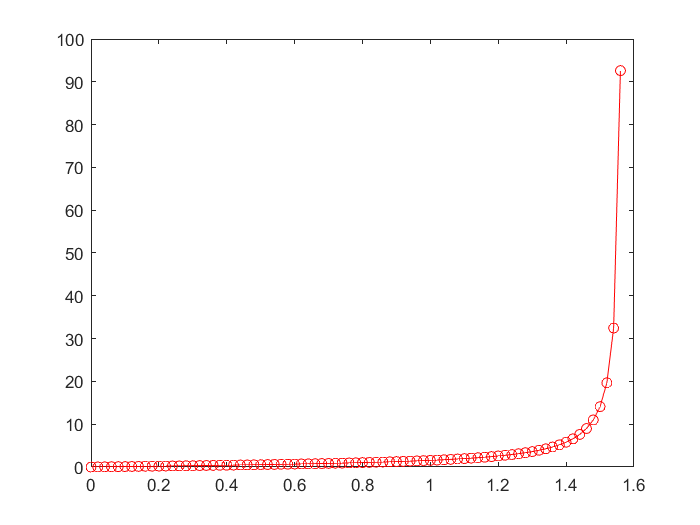

x=[0.1:0.01:60];
y=exp(-0.2*x+10);

plot(x,y)
xlabel('선형축','FontSize',14);
ylabel('선형축','FontSize',14);

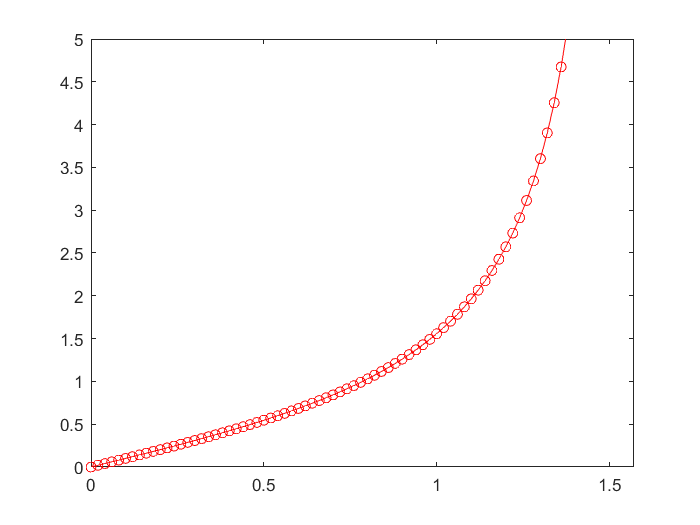

x=[0.1:0.01:60];
y=exp(-0.2*x+10);
semilogy(x,y)

xlabel('선형축','FontSize',14);
ylabel('로그축','FontSize',14);

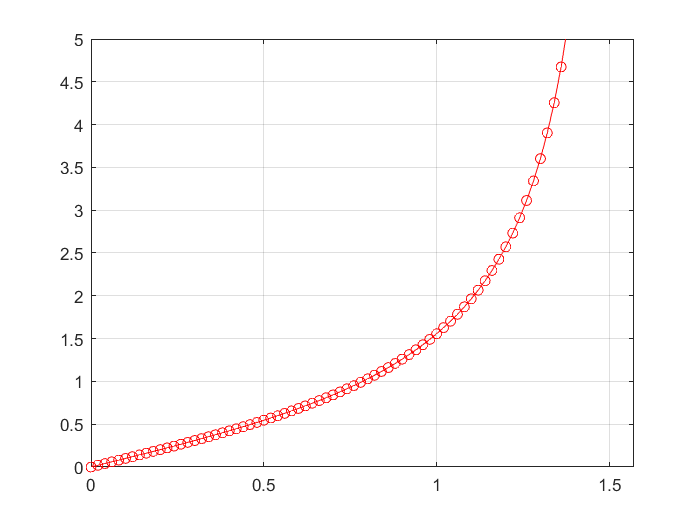

x=[0.1:0.01:60];
y=exp(-0.2*x+10);
semilogx(x,y)
xlabel('로그축','FontSize',14);

ylabel('선형축','FontSize',14);

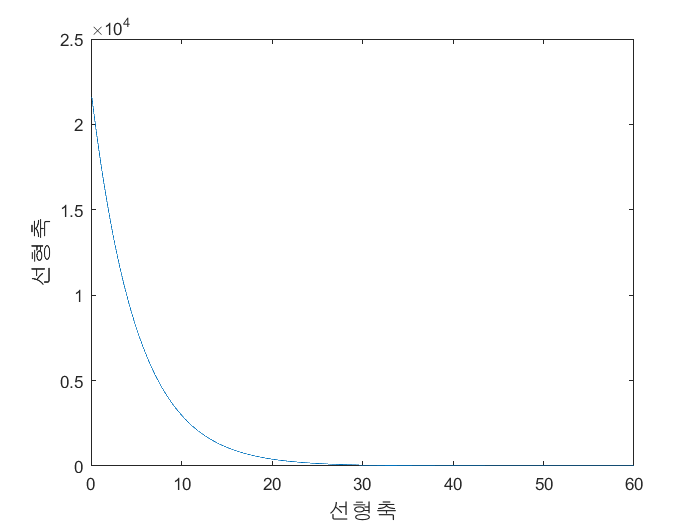

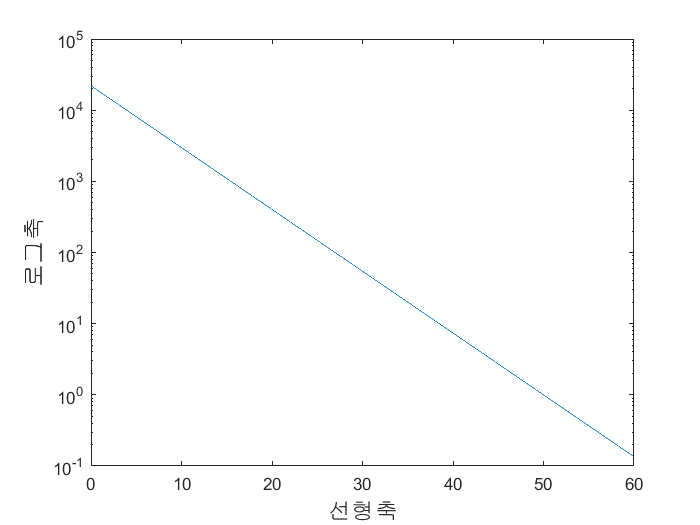

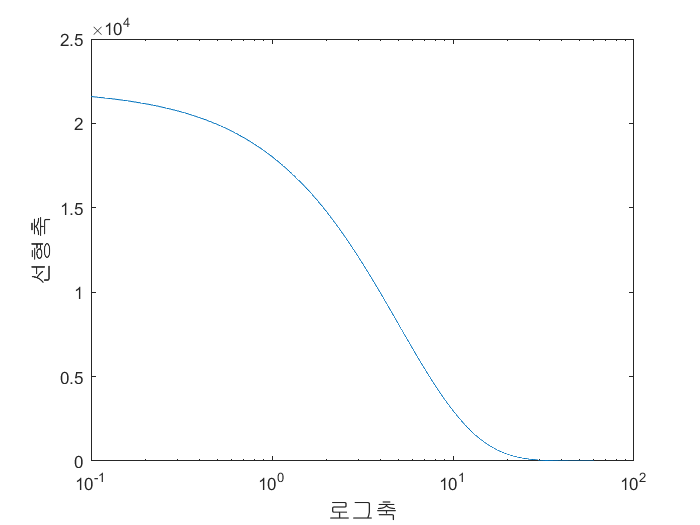

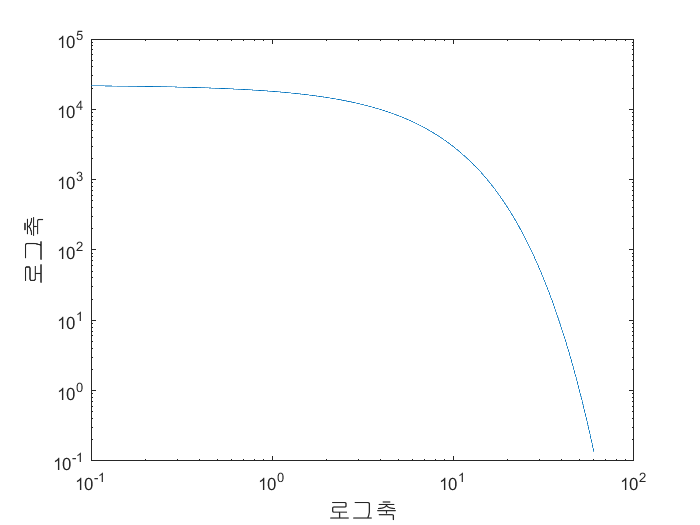

x=[0.1:0.01:60];
y=exp(-0.2*x+10);
loglog(x,y)
xlabel('로그축','FontSize',14);
ylabel('로그축','FontSize',14);